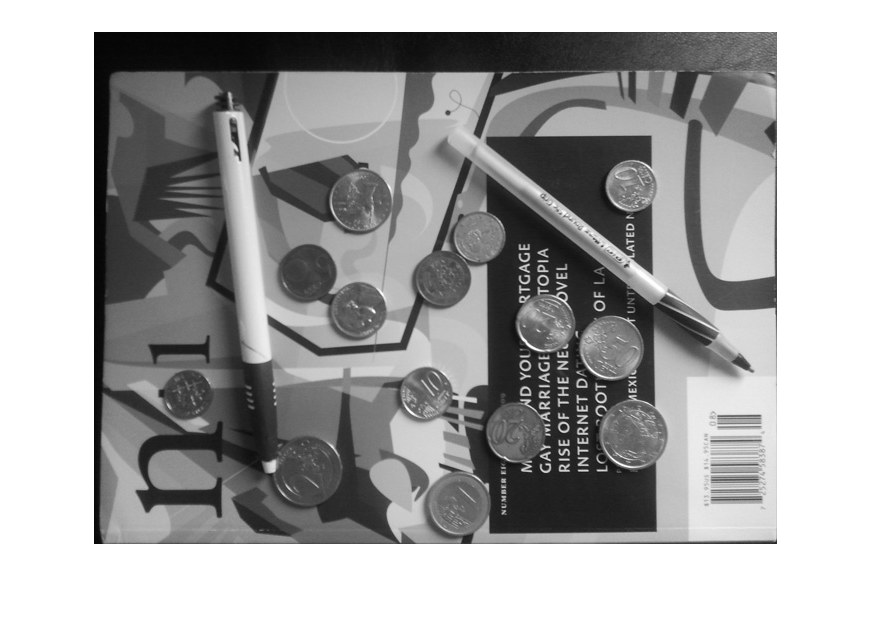

img = rgb2gray(imread("input/ps1-input2.png"));
imshow(img);

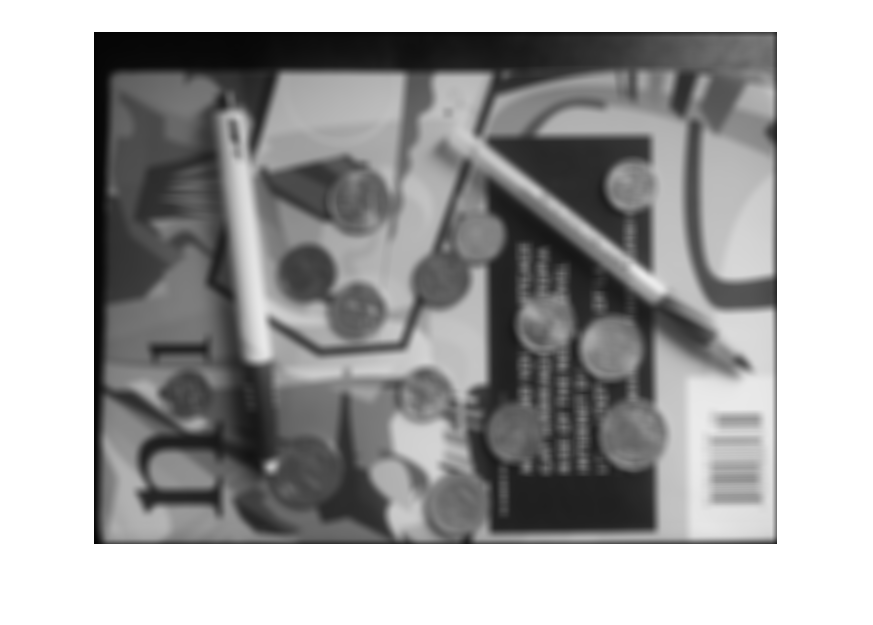

filter = fspecial('gaussian', 11,5);
img_smooth = imfilter(img, filter);
imshow(img_smooth);

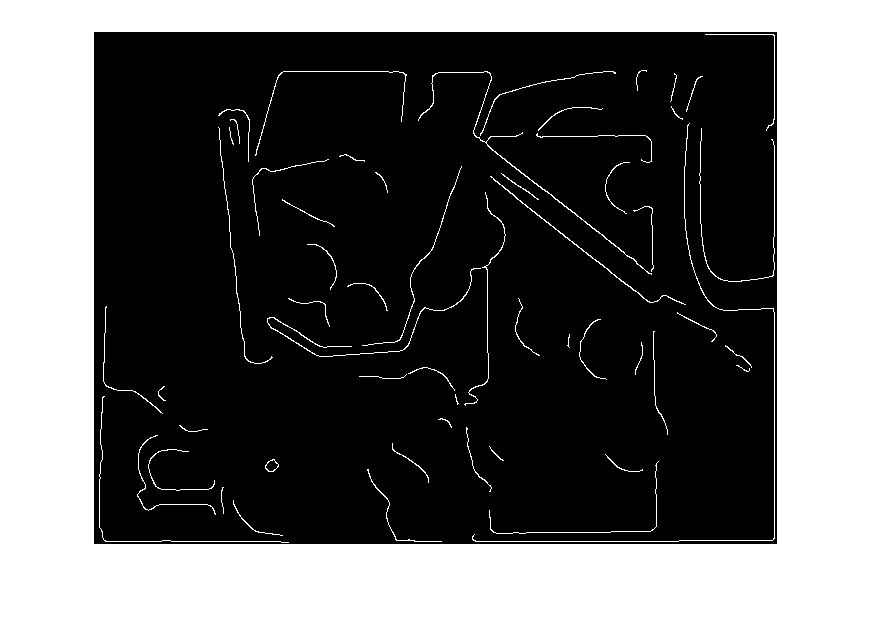

img_smooth_edges = edge(img_smooth,'Canny',[0.4 0.5]);
imshow(img_smooth_edges);

img_edges = img_smooth_edges;


y_bins = 0:size(img_edges,1);
x_bins = 0:size(img_edges,2);
radii = 15:20;


length(y_bins)

ans = 513

length(x_bins)

ans = 684


H = zeros(length(y_bins), length(x_bins) , length(radius));

for r= 1: size(img_edges,1)
    for c= 1: size(img_edges,2)  
        if img_edges(r,c) == 1 
          a = c;
          b = r; 
          for radius = radii
              for x = (a-radius) : (a+radius)
                  if x < 0 
                      continue;
                  end
                  y= sqrt(radius^2 - (x-a)^2) + b;
                  y_i = findbin(y_bins, y);
                  x_i = findbin(x_bins, x);
                  r_i = findbin(radii, radius);
                  H(y_i, x_i, r_i) = H(y_i, x_i, r_i) + 1 ;
              end
          end
       end
    end
end

imshow(H,[]);

Error using images.internal.imageDisplayValidateParams>validateCData (line 118)
Multi-plane image inputs must be RGB images of size MxNx3.

Error in images.internal.imageDisplayValidateParams (lin

maxH = max(H(:))
[maxrowyi , maxcolxi] = find(H >= 0.5*maxH & H<=maxH);
 
a = [maxcolxi,maxrowyi]
 
marks_image = insertMarker(H, a)
colormap gray;
imshow(marks_image,[]);

imshow(img_edges);
for i = 1:size(a,1)
    disp("************circle"+i);
    hold on
    y = y_bins(1,a(i,2));
    x = x_bins(1,a(i,1));
    th = 0:pi/50:2*pi;
    xunit = radius * cos(th) + x;
    yunit = radius * sin(th) + y;
    h = plot(xunit, yunit);
    hold off
end

